%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%svm_model      % SVM模型
%nn_model       % NN模型
%XG_models      % 或 XGmodel，5个XGBoost模型cell
%CTest_data     % 第一个测试集table，包含Label列
%dataTest       % 第二个测试集table，包含Label列
%LabelNames     % XGBoost训练时grp2idx返回的LabelNames
%predictors     % 或 preditors，特征列名
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;
close all;
clear

load("BodyClinicalLevel1.mat","CTest_data");  %加载测试数据
load("BodyClinicalLevel1.mat","svm_model");
load("BodyClinicalLevel1.mat","nn_model");
load("BodyClinicalLevel1.mat","XGmodels");

训练集五折交叉验证准确率 89.17 %.
训练集五折交叉验证精确率 0.8912.
训练集五折交叉验证召回率 0.8880.
训练集五折交叉验证F1分数 0.8890.
独立测试集准确率 89.86 %.
独立测试集精确率 0.9001.
独立测试集召回率 0.8999.
独立测试集F1分数 0.8999.


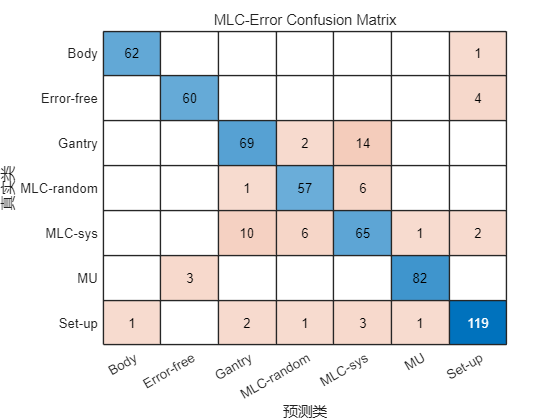

haha

load("BodyClinicalLevel1.mat","selected_feature");
load("BodyClinicalLevel1.mat","dataTrain");
load("BodyClinicalLevel1.mat","dataTest");
load("BodyClinicalLevel1.mat","class_num");
predictors = selected_feature;
%需要重新训练一下XGBoost否则后面无法使用
[metrics_cv_XG,metrics_test_XG,XGmodels,XGclassNames,cm_xg]=XGBoost(dataTrain,dataTest,selected_feature,class_num);

%% 1. Basic settings

B = 2000;
rng(2026, 'twister');

labelName = 'Label';
useStratifiedBootstrap = true;
fprGrid = linspace(0, 1, 501);

outputExcel = 'ML_Bootstrap2000_TwoTestSets.xlsx';

if exist(outputExcel, 'file')
    delete(outputExcel);
end

%% 2. Check required test tables

if ~exist('CTest_data', 'var')
    error('CTest_data not found.');
end

if ~exist('dataTest', 'var')
    error('dataTest not found.');
end

if ~istable(CTest_data)
    error('CTest_data must be a table.');
end

if ~istable(dataTest)
    error('dataTest must be a table.');
end

if ~ismember(labelName, CTest_data.Properties.VariableNames)
    error('CTest_data does not contain Label column.');
end

if ~ismember(labelName, dataTest.Properties.VariableNames)
    error('dataTest does not contain Label column.');
end

%% 3. Get feature names

if exist('predictors', 'var')
    featureNames = predictors;
elseif exist('preditors', 'var')
    featureNames = preditors;
else
    featureNames = CTest_data.Properties.VariableNames;
    featureNames(strcmp(featureNames, labelName)) = [];
end

featureNames = cellstr(featureNames);

fprintf('\nFeature names used for evaluation:\n');


Feature names used for evaluation:


disp(featureNames(:));

    {'original_glszm_SizeZoneNonUniformityNormalized'   }
    {'original_glszm_LargeAreaLowGrayLevelEmphasis'     }
    {'original_glcm_ClusterShade'                       }
    {'original_firstorder_90Percentile'                 }
    {'original_firstorder_10Percentile'                 }
    {'original_gldm_LargeDependenceLowGrayLevelEmphasis'}
    {'original_glszm_ZoneEntropy'                       }
    {'original_firstorder_Mean'                         }
    {'original_firstorder_Skewness'                     }
    {'original_glszm_LargeAreaHighGrayLevelEmphasis'    }
    {'original_glcm_MaximumProbability'                 }
    {'original_glrlm_ShortRunEmphasis'                  }
    {'original_glcm_ClusterProminence'                  }
    {'original_glszm_GrayLevelVariance'                 }
    {'original_glszm_ZonePercentage'                    }
    {'original_firstorder_Kurtosis'                     }
    {'original_glcm_Imc2'                               }
    {'original

## 4. XGBoost class order: MUST use LabelNames from grp2idx

LabelNames = XGclassNames;

if ~exist('LabelNames', 'var')
    error(['LabelNames is missing. For XGBoost evaluation, you must use the LabelNames ' ...
           'returned by [Train_Label, LabelNames] = grp2idx(dataTrain.Label).']);
end

xgbClassOrder = cellstr(LabelNames(:));

fprintf('\n===== XGBoost class order from grp2idx LabelNames =====\n');


===== XGBoost class order from grp2idx LabelNames =====


disp(xgbClassOrder(:));

    {'Error-free'}
    {'Set-up'    }
    {'MLC-random'}
    {'MLC-sys'   }
    {'MU'        }
    {'Gantry'    }
    {'Body'      }




fprintf('\nImportant:\n');


Important:


fprintf('For XGBoost, YScore(:,k) corresponds to xgbClassOrder{k}.\n');

For XGBoost, YScore(:,k) corresponds to xgbClassOrder{k}.




####################################################


Evaluating test set: CTest_data


####################################################



Test set: CTest_data


Sample size: 540


Feature number: 21


Test set: CTest_data | Model: SVM


YScore size = [540, 7]



Class distribution for CTest_data | SVM:
        Class         Count
    ______________    _____

    {'Body'      }      60 
    {'Error-free'}      60 
    {'Gantry'    }      80 
    {'MLC-random'}      60 
    {'MLC-sys'   }      80 
    {'MU'        }      80 
    {'Set-up'    }     120 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


       TestSet         Model           Metric           Estimate    CI_2_5     CI_97_5
    ______________    _______    ___________________    ________    _______    _______

    {'CTest_data'}    {'SVM'}    {'Macro_ROC_AUC'  }    0.86818     0.85181    0.88397
    {'CTest_data'}    {'SVM'}    {'Accuracy'       }    0.62593     0.58889    0.66296
    {'CTest_data'}    {'SVM'}    {'Macro_Precision'}    0.65977     0.62227    0.69864
    {'CTest_data'}    {'SVM'}    {'Macro_Recall'   }     0.6369         0.6    0.67321
    {'CTest_data'}    {'SVM'}    {'Macro_F1'       }    0.62697     0.58789    0.66479



ROC-AUC curve data saved: CTest | SVM


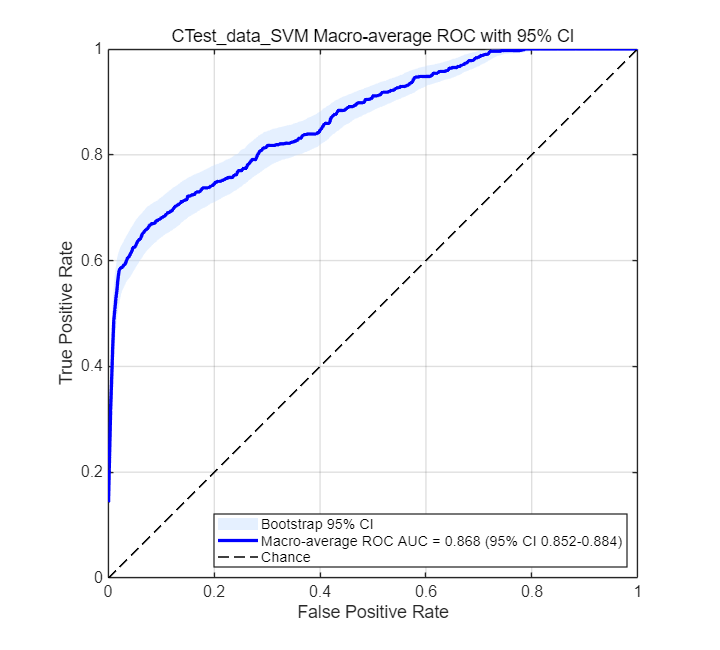

Test set: CTest_data | Model: NN


YScore size = [540, 7]



Class distribution for CTest_data | NN:
        Class         Count
    ______________    _____

    {'Body'      }      60 
    {'Error-free'}      60 
    {'Gantry'    }      80 
    {'MLC-random'}      60 
    {'MLC-sys'   }      80 
    {'MU'        }      80 
    {'Set-up'    }     120 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


       TestSet        Model           Metric           Estimate    CI_2_5     CI_97_5
    ______________    ______    ___________________    ________    _______    _______

    {'CTest_data'}    {'NN'}    {'Macro_ROC_AUC'  }    0.92541     0.91188    0.93861
    {'CTest_data'}    {'NN'}    {'Accuracy'       }    0.72963      0.6963    0.76481
    {'CTest_data'}    {'NN'}    {'Macro_Precision'}    0.76877     0.73516    0.80493
    {'CTest_data'}    {'NN'}    {'Macro_Recall'   }    0.72381     0.68988    0.76012
    {'CTest_data'}    {'NN'}    {'Macro_F1'       }    0.73085     0.69511    0.76799



ROC-AUC curve data saved: CTest | NN


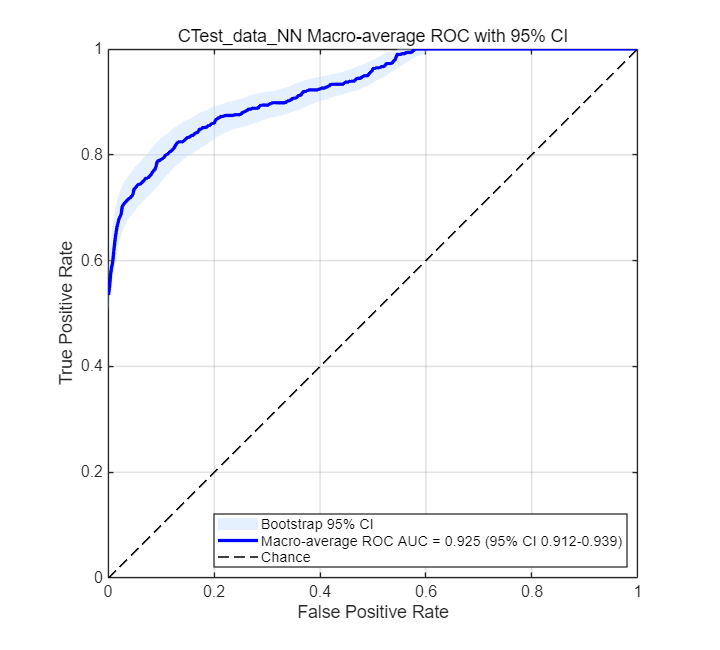

Test set: CTest_data | Model: XGBoost_Ensemble



XGBoost score column order:
    {'Error-free'}
    {'Set-up'    }
    {'MLC-random'}
    {'MLC-sys'   }
    {'MU'        }
    {'Gantry'    }
    {'Body'      }

Predicting XGBoost fold 1 / 5...
Fold 1: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 1: output_margin=true returned N x K margin score.
Predicting XGBoost fold 2 / 5...
Fold 2: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 2: output_margin=true returned N x K margin score.
Predicting XGBoost fold 3 / 5...
Fold 3: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 3: output_margin=true returned N x K margin score.
Predicting XGBoost fold 4 / 5...
Fold 4: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 4: output_margin=true returned N x K margin score.
Predicting XGBoost fold 5 / 5...
Fold 5: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 5: output_margin=true returned N x K margin score.
XGBoost ensemble 

YScore size = [540, 7]



Class distribution for CTest_data | XGBoost_Ensemble:
        Class         Count
    ______________    _____

    {'Error-free'}      60 
    {'Set-up'    }     120 
    {'MLC-random'}      60 
    {'MLC-sys'   }      80 
    {'MU'        }      80 
    {'Gantry'    }      80 
    {'Body'      }      60 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


       TestSet               Model                  Metric           Estimate    CI_2_5     CI_97_5
    ______________    ____________________    ___________________    ________    _______    _______

    {'CTest_data'}    {'XGBoost_Ensemble'}    {'Macro_ROC_AUC'  }    0.91714     0.90251    0.93163
    {'CTest_data'}    {'XGBoost_Ensemble'}    {'Accuracy'       }    0.73889     0.70556    0.77222
    {'CTest_data'}    {'XGBoost_Ensemble'}    {'Macro_Precision'}        0.8     0.77204    0.82917
    {'CTest_data'}    {'XGBoost_Ensemble'}    {'Macro_Recall'   }    0.73274         0.7    0.76548
    {'CTest_data'}    {'XGBoost_Ensemble'}    {'Macro_F1'       }    0.73596     0.70027    0.77103



ROC-AUC curve data saved: CTest | XGB


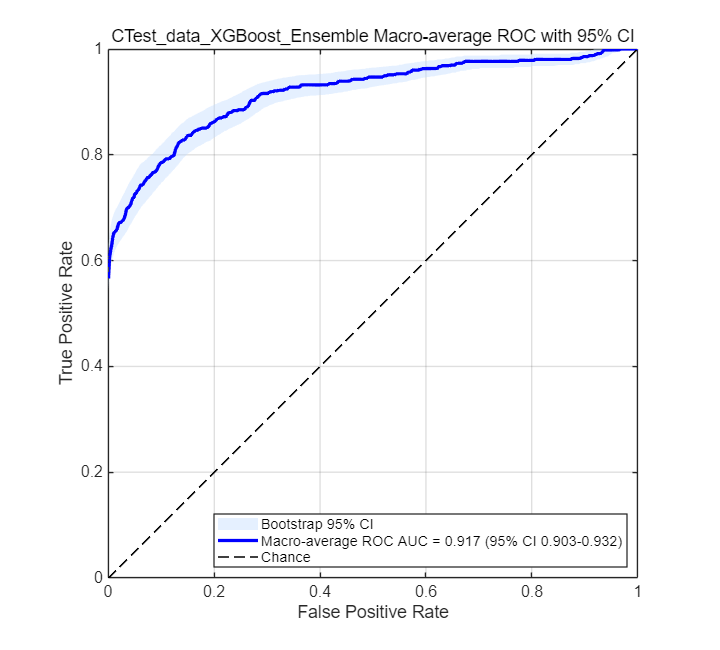



####################################################


Evaluating test set: dataTest


####################################################



Test set: dataTest


Sample size: 572


Feature number: 21


Test set: dataTest | Model: SVM


YScore size = [572, 7]



Class distribution for dataTest | SVM:
        Class         Count
    ______________    _____

    {'Body'      }      63 
    {'Error-free'}      64 
    {'Gantry'    }      85 
    {'MLC-random'}      64 
    {'MLC-sys'   }      84 
    {'MU'        }      85 
    {'Set-up'    }     127 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


      TestSet        Model           Metric           Estimate    CI_2_5     CI_97_5
    ____________    _______    ___________________    ________    _______    _______

    {'dataTest'}    {'SVM'}    {'Macro_ROC_AUC'  }    0.96344     0.95418     0.9714
    {'dataTest'}    {'SVM'}    {'Accuracy'       }    0.81643     0.78671    0.84528
    {'dataTest'}    {'SVM'}    {'Macro_Precision'}    0.82555     0.79477    0.85641
    {'dataTest'}    {'SVM'}    {'Macro_Recall'   }    0.81383     0.78071    0.84302
    {'dataTest'}    {'SVM'}    {'Macro_F1'       }    0.81668     0.78431    0.84622



ROC-AUC curve data saved: DTest | SVM


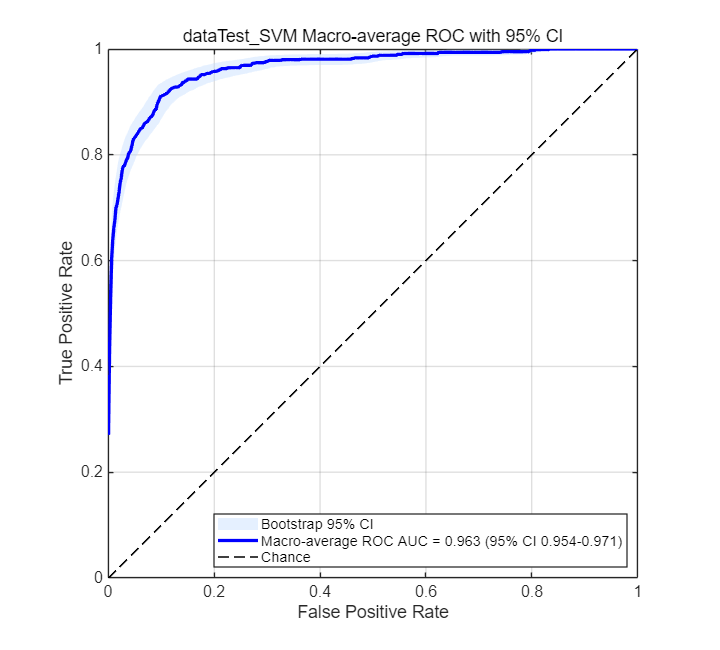

Test set: dataTest | Model: NN


YScore size = [572, 7]



Class distribution for dataTest | NN:
        Class         Count
    ______________    _____

    {'Body'      }      63 
    {'Error-free'}      64 
    {'Gantry'    }      85 
    {'MLC-random'}      64 
    {'MLC-sys'   }      84 
    {'MU'        }      85 
    {'Set-up'    }     127 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


      TestSet       Model           Metric           Estimate    CI_2_5     CI_97_5
    ____________    ______    ___________________    ________    _______    _______

    {'dataTest'}    {'NN'}    {'Macro_ROC_AUC'  }    0.98691     0.98212    0.99104
    {'dataTest'}    {'NN'}    {'Accuracy'       }    0.88636     0.86014    0.90909
    {'dataTest'}    {'NN'}    {'Macro_Precision'}    0.89353     0.87025     0.9167
    {'dataTest'}    {'NN'}    {'Macro_Recall'   }    0.88596     0.85927    0.91036
    {'dataTest'}    {'NN'}    {'Macro_F1'       }    0.88925     0.86352    0.91251



ROC-AUC curve data saved: DTest | NN


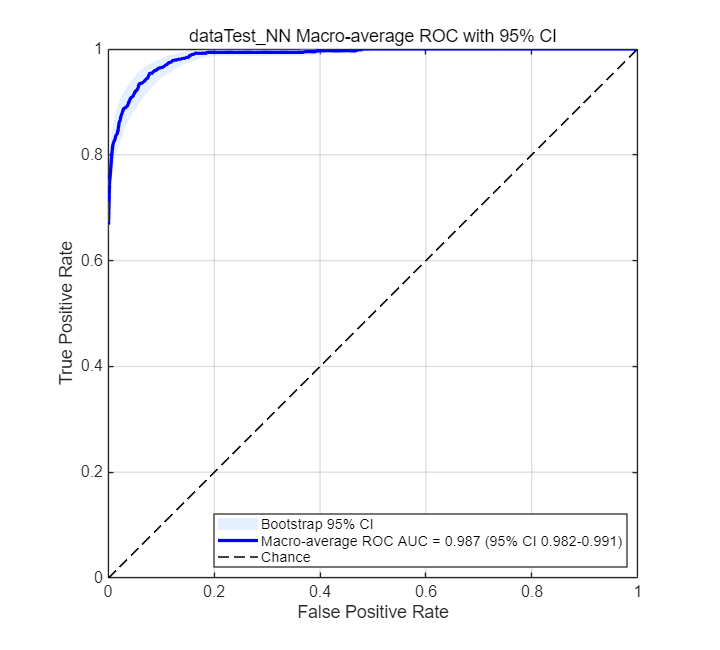

Test set: dataTest | Model: XGBoost_Ensemble



XGBoost score column order:
    {'Error-free'}
    {'Set-up'    }
    {'MLC-random'}
    {'MLC-sys'   }
    {'MU'        }
    {'Gantry'    }
    {'Body'      }

Predicting XGBoost fold 1 / 5...
Fold 1: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 1: output_margin=true returned N x K margin score.
Predicting XGBoost fold 2 / 5...
Fold 2: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 2: output_margin=true returned N x K margin score.
Predicting XGBoost fold 3 / 5...
Fold 3: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 3: output_margin=true returned N x K margin score.
Predicting XGBoost fold 4 / 5...
Fold 4: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 4: output_margin=true returned N x K margin score.
Predicting XGBoost fold 5 / 5...
Fold 5: predict(DTest) returned N x 1 labels. Trying output_margin=true...
Fold 5: output_margin=true returned N x K margin score.
XGBoost ensemble 

YScore size = [572, 7]



Class distribution for dataTest | XGBoost_Ensemble:
        Class         Count
    ______________    _____

    {'Error-free'}      64 
    {'Set-up'    }     127 
    {'MLC-random'}      64 
    {'MLC-sys'   }      84 
    {'MU'        }      85 
    {'Gantry'    }      85 
    {'Body'      }      63 



Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


      TestSet              Model                  Metric           Estimate    CI_2_5     CI_97_5
    ____________    ____________________    ___________________    ________    _______    _______

    {'dataTest'}    {'XGBoost_Ensemble'}    {'Macro_ROC_AUC'  }    0.98713     0.98305    0.99056
    {'dataTest'}    {'XGBoost_Ensemble'}    {'Accuracy'       }     0.8951     0.86888    0.91783
    {'dataTest'}    {'XGBoost_Ensemble'}    {'Macro_Precision'}    0.89776     0.87232    0.92134
    {'dataTest'}    {'XGBoost_Ensemble'}    {'Macro_Recall'   }    0.89657     0.87008    0.91992
    {'dataTest'}    {'XGBoost_Ensemble'}    {'Macro_F1'       }    0.89705     0.87087    0.91993



ROC-AUC curve data saved: DTest | XGB


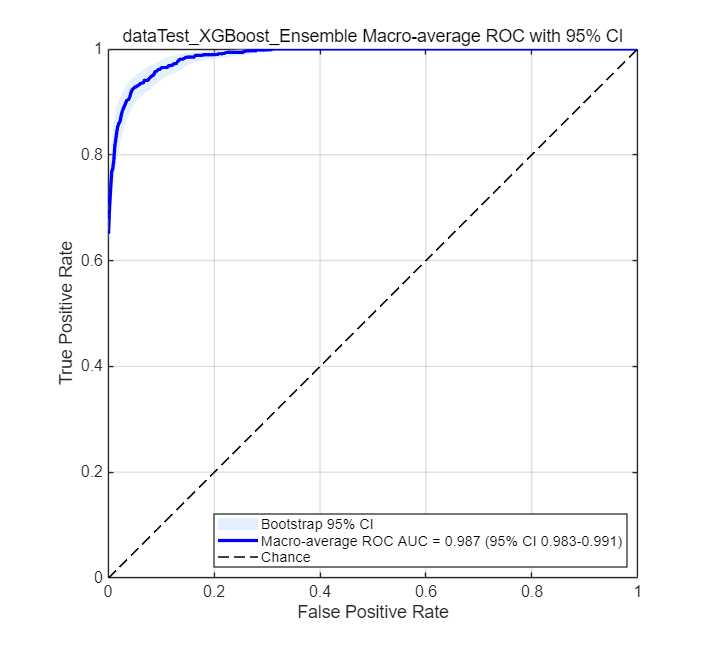


%% 5. Check XGBoost model cell

if exist('XGmodels', 'var')
    XGBoostModels = XGmodels;
elseif exist('XGmodel', 'var')
    XGBoostModels = XGmodel;
else
    error('XGBoost model cell not found. Please provide XG_models or XGmodel.');
end

if ~iscell(XGBoostModels)
    error('XGBoostModels must be a cell array, e.g., XG_models{1}, ..., XG_models{5}.');
end

%% 6. Define test sets

testSets = struct([]);

testSets(1).Name = 'CTest_data';
testSets(1).Tag  = 'CTest';
testSets(1).Data = CTest_data;

testSets(2).Name = 'dataTest';
testSets(2).Tag  = 'DTest';
testSets(2).Data = dataTest;

%% 7. Define model list

modelDefs = struct([]);

modelDefs(1).Name = 'SVM';
modelDefs(1).Tag  = 'SVM';
modelDefs(1).Type = 'MATLAB';
modelDefs(1).Obj  = svm_model;

modelDefs(2).Name = 'NN';
modelDefs(2).Tag  = 'NN';
modelDefs(2).Type = 'MATLAB';
modelDefs(2).Obj  = nn_model;

modelDefs(3).Name = 'XGBoost_Ensemble';
modelDefs(3).Tag  = 'XGB';
modelDefs(3).Type = 'XGBoostEnsemble';
modelDefs(3).Obj  = XGBoostModels;

%% 8. Main loop: each test set × each model

summaryResults = table();

for t = 1:numel(testSets)

    testName = testSets(t).Name;
    testTag  = testSets(t).Tag;
    thisData = testSets(t).Data;

    fprintf('\n\n####################################################\n');
    fprintf('Evaluating test set: %s\n', testName);
    fprintf('####################################################\n');

    %% 8.1 Prepare test data

    [YTrueRaw, XTestTable, numSamples] = prepareTestTable( ...
        thisData, ...
        labelName, ...
        featureNames);

    fprintf('\nTest set: %s\n', testName);
    fprintf('Sample size: %d\n', numSamples);
    fprintf('Feature number: %d\n', width(XTestTable));

    %% 8.2 Evaluate each model on this test set

    for m = 1:numel(modelDefs)

        modelName = modelDefs(m).Name;
        modelTag  = modelDefs(m).Tag;
        modelType = modelDefs(m).Type;
        modelObj  = modelDefs(m).Obj;

        fprintf('\n====================================================\n');
        fprintf('Test set: %s | Model: %s\n', testName, modelName);
        fprintf('====================================================\n');

        switch modelType

            case 'MATLAB'

                %% SVM / NN:
                % score列顺序按照模型自身ClassNames解释。
                [scoreRaw, modelClassNames] = predictMATLABModelScore( ...
                    modelObj, ...
                    XTestTable);

                if isempty(modelClassNames)
                    warning('%s: model ClassNames not found. Using categories from current test set.', modelName);
                    modelClassNames = cellstr(categories(categorical(YTrueRaw)));
                end

                evalClassOrder = cellstr(modelClassNames(:));

                YScore = alignScoreColumns( ...
                    scoreRaw, ...
                    modelClassNames, ...
                    evalClassOrder, ...
                    numSamples);

            case 'XGBoostEnsemble'

                %% XGBoost:
                % score列顺序必须按照LabelNames解释。
                evalClassOrder = xgbClassOrder;

                YScore = predictXGBoostEnsembleScore( ...
                    modelObj, ...
                    XTestTable, ...
                    evalClassOrder);

            otherwise

                error('Unknown model type.');
        end

        fprintf('YScore size = [%d, %d]\n', size(YScore, 1), size(YScore, 2));

        if size(YScore, 1) ~= numSamples
            error('%s | %s: YScore row number does not match test sample size.', testName, modelName);
        end

        if size(YScore, 2) ~= numel(evalClassOrder)
            error('%s | %s: YScore column number does not match class number.', testName, modelName);
        end

        if any(~isfinite(YScore(:)))
            error('%s | %s: YScore contains NaN or Inf.', testName, modelName);
        end

        %% 8.3 Print class distribution under current evalClassOrder

        printClassDistribution(YTrueRaw, evalClassOrder, [testName, ' | ', modelName]);

        %% 8.4 Bootstrap evaluation

        positiveClass = '';

        [resultTable, rocOut, bootMetricTable] = bootstrapEvaluation2000( ...
            YTrueRaw, ...
            YScore, ...
            evalClassOrder, ...
            positiveClass, ...
            B, ...
            useStratifiedBootstrap, ...
            fprGrid);

        testColumn  = repmat({testName}, height(resultTable), 1);
        modelColumn = repmat({modelName}, height(resultTable), 1);

        resultTable = [ ...
            table(testColumn, modelColumn, 'VariableNames', {'TestSet', 'Model'}), ...
            resultTable];

        summaryResults = [summaryResults; resultTable]; %#ok<AGROW>

        disp(resultTable);

        %% 8.5 Save bootstrap metrics

        bootSheet = makeShortSheetName(testTag, modelTag, 'Boot');

        writetable( ...
            bootMetricTable, ...
            outputExcel, ...
            'Sheet', bootSheet);

        %% 8.6 Save detailed ROC-AUC curve data to Excel

        saveROCAUCDataToExcel( ...
            YTrueRaw, ...
            YScore, ...
            evalClassOrder, ...
            rocOut, ...
            outputExcel, ...
            testTag, ...
            modelTag, ...
            fprGrid);

        %% 8.7 Plot ROC with 95% CI

        plotROCWithCI(rocOut, [testName, '_', modelName], numel(evalClassOrder));

        figBaseName = [testTag, '_', modelTag, '_ROC_95CI'];

        saveas(gcf, [figBaseName, '.png']);
        savefig(gcf, [figBaseName, '.fig']);

    end
end


%% 9. Save summary table

writetable( ...
    summaryResults, ...
    outputExcel, ...
    'Sheet', 'Summary');

fprintf('\n====================================================\n');

fprintf('Bootstrap 2000 evaluation completed for CTest_data and dataTest.\n');

Bootstrap 2000 evaluation completed for CTest_data and dataTest.


fprintf('Results saved to: %s\n', outputExcel);

Results saved to: ML_Bootstrap2000_TwoTestSets.xlsx


fprintf('====================================================\n');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数1%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [YTrueRaw, XTestTable, numSamples] = prepareTestTable( ...
    dataTable, ...
    labelName, ...
    featureNames)

if ~istable(dataTable)
    error('Input data must be a table.');
end

if ~ismember(labelName, dataTable.Properties.VariableNames)
    error('Input data table does not contain label column.');
end

missingFeatures = setdiff(featureNames, dataTable.Properties.VariableNames);

if ~isempty(missingFeatures)
    disp('Missing feature columns:');
    disp(missingFeatures(:));
    error('Some required feature columns are missing in this test set.');
end

YTrueRaw = dataTable.(labelName);
XTestTable = dataTable(:, featureNames);

isNum = varfun(@isnumeric, XTestTable, 'OutputFormat', 'uniform');

if ~all(isNum)
    badVars = XTestTable.Properties.VariableNames(~isNum);
    error('The following feature columns are not numeric: %s', strjoin(badVars, ', '));
end

numSamples = height(dataTable);

if numSamples ~= numel(YTrueRaw)
    error('Label number does not match table height.');
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数2%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [score, classNames] = predictMATLABModelScore(model, XTestTable)
%PREDICTMATLABMODELSCORE
%
% For MATLAB classification models:
%   SVM, ECOC-SVM, fitcnet, ClassificationNeuralNetwork, etc.
%
% Output:
%   score      N x K
%   classNames score column order

score = [];

try
    [~, score] = predict(model, XTestTable);
catch ME1

    try
        [~, score] = predict(model, table2array(XTestTable));
    catch ME2

        error( ...
            'MATLAB model prediction failed.\nTable input error: %s\nArray input error: %s', ...
            ME1.message, ME2.message);
    end
end

if istable(score)
    score = table2array(score);
end

score = double(score);

classNames = extractClassNames(model);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数3%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function YScore = predictXGBoostEnsembleScore(XGBoostModels, XTestTable, xgbClassOrder)
%PREDICTXGBOOSTENSEMBLESCORE
%
% Key rule:
%   The output YScore(:,k) corresponds to xgbClassOrder{k}.
%
% xgbClassOrder must be LabelNames from:
%   [Train_Label, LabelNames] = grp2idx(dataTrain.Label);
%   Train_Label = Train_Label - 1;
%
% If XGBoost was trained with multi:softprob:
%   predict(DTest) returns N x K probabilities.
%
% If XGBoost was trained with multi:softmax:
%   predict(DTest) returns N x 1 labels.
%   Then this function tries output_margin=true to get N x K margin scores.

if ~iscell(XGBoostModels)
    error('XGBoostModels must be a cell array.');
end

xgbClassOrder = cellstr(xgbClassOrder(:));

numModels = numel(XGBoostModels);
numSamples = height(XTestTable);
numClasses = numel(xgbClassOrder);

XArray = table2array(XTestTable);
XPy = py.numpy.array(XArray);
DTest = py.xgboost.DMatrix(XPy);

scoreAll = zeros(numSamples, numClasses, numModels);

fprintf('\nXGBoost score column order:\n');
disp(xgbClassOrder(:));

for i = 1:numModels

    fprintf('Predicting XGBoost fold %d / %d...\n', i, numModels);

    model = XGBoostModels{i};

    %% 1. First try predict(DTest)
    pred = model.predict(DTest);
    predVec = pyArrayToDoubleVector(pred);

    if numel(predVec) == numSamples * numClasses

        % multi:softprob or probability-like output
        score_i = reshape(predVec, numClasses, [])';

        fprintf('Fold %d: predict(DTest) returned N x K score/probability.\n', i);

    elseif numel(predVec) == numSamples

        % multi:softmax, predict returns class label only
        fprintf(['Fold %d: predict(DTest) returned N x 1 labels. ' ...
                 'Trying output_margin=true...\n'], i);

        predMargin = model.predict(DTest, pyargs('output_margin', true));
        marginVec = pyArrayToDoubleVector(predMargin);

        if numel(marginVec) ~= numSamples * numClasses
            error(['Fold %d: output_margin is not N x K.\n' ...
                   'Current length = %d, expected = %d.\n' ...
                   'Recommendation: retrain XGBoost with objective = multi:softprob.'], ...
                   i, numel(marginVec), numSamples * numClasses);
        end

        score_i = reshape(marginVec, numClasses, [])';

        fprintf('Fold %d: output_margin=true returned N x K margin score.\n', i);

    else

        error(['Fold %d: unexpected XGBoost output length.\n' ...
               'Length = %d, N = %d, K = %d.'], ...
               i, numel(predVec), numSamples, numClasses);
    end

    if size(score_i, 1) ~= numSamples || size(score_i, 2) ~= numClasses
        error('Fold %d: score_i has wrong size.', i);
    end

    scoreAll(:, :, i) = score_i;
end

YScore = mean(scoreAll, 3);

fprintf('XGBoost ensemble YScore size = [%d, %d]\n', size(YScore, 1), size(YScore, 2));
fprintf('YScore columns correspond to LabelNames / xgbClassOrder.\n');

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数4%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function vec = pyArrayToDoubleVector(pyArray)
%PYARRAYTODOUBLEVECTOR
% Convert Python numpy array to MATLAB double column vector.

try
    vec = double(py.array.array('d', py.numpy.nditer(pyArray)));
catch
    try
        vec = double(pyArray);
    catch ME
        error('Failed to convert Python array to MATLAB double: %s', ME.message);
    end
end

vec = vec(:);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数5%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function scoreOut = alignScoreColumns(scoreIn, modelClassNames, targetClassOrder, numSamples)
%ALIGNSCORECOLUMNS
%
% scoreIn(:,j) corresponds to modelClassNames{j}.
% scoreOut(:,k) corresponds to targetClassOrder{k}.

scoreIn = double(scoreIn);

modelClassNames = cellstr(modelClassNames(:));
targetClassOrder = cellstr(targetClassOrder(:));

numClasses = numel(targetClassOrder);

%% If score is K x N, transpose to N x K
if size(scoreIn, 1) ~= numSamples && size(scoreIn, 2) == numSamples
    scoreIn = scoreIn';
end

%% Binary classifier returns only one score column
if isvector(scoreIn)

    scoreIn = scoreIn(:);

    if numel(scoreIn) ~= numSamples
        error('One-dimensional score length does not match sample size.');
    end

    if numClasses ~= 2
        error('Multiclass task cannot use a one-column score.');
    end

    if all(scoreIn >= 0 & scoreIn <= 1)
        scoreIn = [1 - scoreIn, scoreIn];
    else
        scoreIn = [-scoreIn, scoreIn];
    end

    modelClassNames = targetClassOrder;
end

%% Check size
if size(scoreIn, 1) ~= numSamples
    error('score row number = %d, sample size = %d.', size(scoreIn, 1), numSamples);
end

if size(scoreIn, 2) ~= numClasses
    error('score column number = %d, class number = %d.', size(scoreIn, 2), numClasses);
end

%% Match class names
[tf, loc] = ismember(targetClassOrder, modelClassNames);

if any(~tf)

    fprintf('\nTarget class order:\n');
    disp(targetClassOrder(:));

    fprintf('\nModel score class order:\n');
    disp(modelClassNames(:));

    fprintf('\nUnmatched classes:\n');
    disp(targetClassOrder(~tf));

    error('Cannot align score columns. Please check class names.');
end

scoreOut = scoreIn(:, loc);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数6%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [resultTable, rocOut, bootMetricTable] = bootstrapEvaluation2000( ...
    YTrueRaw, ...
    YScore, ...
    classOrder, ...
    positiveClass, ...
    B, ...
    useStratifiedBootstrap, ...
    fprGrid)
%BOOTSTRAPEVALUATION2000
%
% Binary:
%   ROC_AUC, Accuracy, Precision, Recall, F1_score
%
% Multiclass:
%   Macro_ROC_AUC, Accuracy, Macro_Precision, Macro_Recall, Macro_F1
%
% CI:
%   2.5% and 97.5% percentile from bootstrap samples

classOrder = cellstr(classOrder(:));

trueLabels = labelsToCellstr(YTrueRaw);

[tf, trueIndex] = ismember(trueLabels, classOrder);

if any(~tf)
    fprintf('\nLabels in YTrue not found in current classOrder:\n');
    disp(unique(trueLabels(~tf)));
    fprintf('\nCurrent classOrder:\n');
    disp(classOrder(:));
    error('YTrue contains labels not included in classOrder.');
end

numSamples = numel(trueIndex);
numClasses = numel(classOrder);

if size(YScore, 1) ~= numSamples
    error('YScore rows do not match YTrue sample size.');
end

if size(YScore, 2) ~= numClasses
    error('YScore columns do not match classOrder.');
end

if numClasses == 2 && isempty(positiveClass)
    positiveClass = classOrder{end};
end

%% 1. Point estimates on full test set

pointMetrics = computeMetricsFromScore( ...
    trueIndex, ...
    YScore, ...
    classOrder, ...
    positiveClass);

[pointTPR, pointAUC] = computeROCFromScore( ...
    trueIndex, ...
    YScore, ...
    classOrder, ...
    positiveClass, ...
    fprGrid);

pointMetrics(1) = pointAUC;

%% 2. Bootstrap

numMetrics = 5;

bootMetrics = nan(B, numMetrics);
bootTPR = nan(B, numel(fprGrid));

for b = 1:B

    if useStratifiedBootstrap
        idx = stratifiedBootstrapIndex(trueIndex, numClasses);
    else
        idx = randi(numSamples, numSamples, 1);
    end

    yb = trueIndex(idx);
    sb = YScore(idx, :);

    mb = computeMetricsFromScore( ...
        yb, ...
        sb, ...
        classOrder, ...
        positiveClass);

    [tprB, aucB] = computeROCFromScore( ...
        yb, ...
        sb, ...
        classOrder, ...
        positiveClass, ...
        fprGrid);

    mb(1) = aucB;

    bootMetrics(b, :) = mb;
    bootTPR(b, :) = tprB;

    if mod(b, 200) == 0
        fprintf('Bootstrap %d / %d completed.\n', b, B);
    end
end

%% 3. 95% CI for metrics

ciLower = nan(numMetrics, 1);
ciUpper = nan(numMetrics, 1);

for j = 1:numMetrics

    temp = bootMetrics(:, j);
    temp = temp(isfinite(temp));

    if ~isempty(temp)
        ci = prctile(temp, [2.5, 97.5]);
        ciLower(j) = ci(1);
        ciUpper(j) = ci(2);
    end
end

%% 4. Pointwise 95% CI for ROC curve

tprLower = nan(size(fprGrid));
tprUpper = nan(size(fprGrid));

for j = 1:numel(fprGrid)

    temp = bootTPR(:, j);
    temp = temp(isfinite(temp));

    if ~isempty(temp)
        ci = prctile(temp, [2.5, 97.5]);
        tprLower(j) = ci(1);
        tprUpper(j) = ci(2);
    end
end

%% 5. Output table

if numClasses == 2
    metricNames = {
        'ROC_AUC';
        'Accuracy';
        'Precision';
        'Recall';
        'F1_score'
        };
else
    metricNames = {
        'Macro_ROC_AUC';
        'Accuracy';
        'Macro_Precision';
        'Macro_Recall';
        'Macro_F1'
        };
end

estimateValues = pointMetrics(:);
ciLower = ciLower(:);
ciUpper = ciUpper(:);

resultTable = table( ...
    metricNames, ...
    estimateValues, ...
    ciLower, ...
    ciUpper, ...
    'VariableNames', ...
    {'Metric', 'Estimate', 'CI_2_5', 'CI_97_5'});

validMetricNames = matlab.lang.makeValidName(metricNames);

bootMetricTable = array2table( ...
    bootMetrics, ...
    'VariableNames', ...
    validMetricNames);

%% 6. ROC output

rocOut = struct();

rocOut.FPR = fprGrid;
rocOut.TPR = pointTPR;
rocOut.TPRLower = tprLower;
rocOut.TPRUpper = tprUpper;

rocOut.AUC = pointMetrics(1);
rocOut.AUCLower = ciLower(1);
rocOut.AUCUpper = ciUpper(1);

rocOut.NumClasses = numClasses;
rocOut.PositiveClass = positiveClass;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数7%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function metricVector = computeMetricsFromScore(trueIndex, YScore, classOrder, positiveClass)
%COMPUTEMETRICSFROMSCORE
%
% Output:
%   [AUC; Accuracy; Precision; Recall; F1]

numClasses = numel(classOrder);

[~, predIndex] = max(YScore, [], 2);

accuracy = mean(predIndex == trueIndex);

support = zeros(numClasses, 1);

for k = 1:numClasses
    support(k) = sum(trueIndex == k);
end

%% Binary classification
if numClasses == 2

    positiveIndex = getPositiveIndex(classOrder, positiveClass);

    yPos = trueIndex == positiveIndex;
    predPos = predIndex == positiveIndex;

    TP = sum(yPos & predPos);
    FP = sum(~yPos & predPos);
    FN = sum(yPos & ~predPos);

    precision = safeDivide(TP, TP + FP);
    recall = safeDivide(TP, TP + FN);
    f1 = safeF1(precision, recall);

    if numel(unique(yPos)) < 2
        auc = NaN;
    else
        [~, ~, ~, auc] = perfcurve(yPos, YScore(:, positiveIndex), true);
    end

%% Multiclass classification
else

    precisionEach = nan(numClasses, 1);
    recallEach = nan(numClasses, 1);
    f1Each = nan(numClasses, 1);
    aucEach = nan(numClasses, 1);

    for k = 1:numClasses

        if support(k) == 0
            continue;
        end

        yPos = trueIndex == k;
        predPos = predIndex == k;

        TP = sum(yPos & predPos);
        FP = sum(~yPos & predPos);
        FN = sum(yPos & ~predPos);

        precisionEach(k) = safeDivide(TP, TP + FP);
        recallEach(k) = safeDivide(TP, TP + FN);
        f1Each(k) = safeF1(precisionEach(k), recallEach(k));

        if numel(unique(yPos)) >= 2
            [~, ~, ~, aucEach(k)] = perfcurve(yPos, YScore(:, k), true);
        end
    end

    precision = meanOmitNaN(precisionEach);
    recall = meanOmitNaN(recallEach);
    f1 = meanOmitNaN(f1Each);
    auc = meanOmitNaN(aucEach);
end

metricVector = [
    auc;
    accuracy;
    precision;
    recall;
    f1
    ];

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数8%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [meanTPR, meanAUC] = computeROCFromScore( ...
    trueIndex, ...
    YScore, ...
    classOrder, ...
    positiveClass, ...
    fprGrid)
%COMPUTEROCFROMSCORE
%
% Binary:
%   ROC for positive class
%
% Multiclass:
%   one-vs-rest macro-average ROC

numClasses = numel(classOrder);

%% Binary ROC
if numClasses == 2

    positiveIndex = getPositiveIndex(classOrder, positiveClass);

    yPos = trueIndex == positiveIndex;

    if numel(unique(yPos)) < 2
        meanTPR = nan(size(fprGrid));
        meanAUC = NaN;
        return;
    end

    [FPR, TPR, ~, meanAUC] = perfcurve( ...
        yPos, ...
        YScore(:, positiveIndex), ...
        true);

    meanTPR = interpROC(FPR, TPR, fprGrid);

%% Multiclass macro ROC
else

    tprEach = nan(numClasses, numel(fprGrid));
    aucEach = nan(numClasses, 1);

    for k = 1:numClasses

        yPos = trueIndex == k;

        if numel(unique(yPos)) < 2
            continue;
        end

        [FPR, TPR, ~, aucEach(k)] = perfcurve( ...
            yPos, ...
            YScore(:, k), ...
            true);

        tprEach(k, :) = interpROC(FPR, TPR, fprGrid);
    end

    meanTPR = meanRowsOmitNaN(tprEach);
    meanAUC = meanOmitNaN(aucEach);
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数9%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function saveROCAUCDataToExcel( ...
    YTrueRaw, ...
    YScore, ...
    classOrder, ...
    rocOut, ...
    outputExcel, ...
    testTag, ...
    modelTag, ...
    fprGrid)
%SAVEROCAUCDATATOEXCEL
%
% Save ROC-AUC curve data to Excel.
%
% Output:
% 1. Macro ROC:
%    FPR, Macro_TPR, Macro_TPR_95CI_Lower, Macro_TPR_95CI_Upper
%
% 2. Per-class ROC:
%    FPR, TPR_Class1, TPR_Class2, ...
%
% 3. Per-class AUC:
%    Class, One_vs_Rest_AUC
%
% For multiclass tasks, one-vs-rest ROC is used.

classOrder = cellstr(classOrder(:));
numClasses = numel(classOrder);

trueLabels = labelsToCellstr(YTrueRaw);

[tf, trueIndex] = ismember(trueLabels, classOrder);

if any(~tf)
    disp('YTrueRaw labels not found in classOrder:');
    disp(unique(trueLabels(~tf)));
    error('saveROCAUCDataToExcel: labels not found in classOrder.');
end

if size(YScore, 1) ~= numel(trueIndex)
    error('YScore rows do not match sample size.');
end

if size(YScore, 2) ~= numClasses
    error('YScore columns do not match class number.');
end

%% 1. Save Macro ROC curve

macroROCTable = table( ...
    rocOut.FPR(:), ...
    rocOut.TPR(:), ...
    rocOut.TPRLower(:), ...
    rocOut.TPRUpper(:), ...
    'VariableNames', ...
    {'FPR', 'Macro_TPR', 'Macro_TPR_95CI_Lower', 'Macro_TPR_95CI_Upper'});

macroSheet = makeShortSheetName(testTag, modelTag, 'ROCM');

writetable( ...
    macroROCTable, ...
    outputExcel, ...
    'Sheet', macroSheet);

%% 2. Save per-class one-vs-rest ROC curve

tprEachClass = nan(numel(fprGrid), numClasses);
aucEachClass = nan(numClasses, 1);

for k = 1:numClasses

    yBinary = trueIndex == k;
    scoreK = YScore(:, k);

    if numel(unique(yBinary)) < 2
        warning('Class %s lacks positive or negative samples. AUC cannot be calculated.', classOrder{k});
        continue;
    end

    [FPR, TPR, ~, aucK] = perfcurve(yBinary, scoreK, true);

    tprEachClass(:, k) = interpROC(FPR, TPR, fprGrid(:));
    aucEachClass(k) = aucK;
end

rocClassTable = table(fprGrid(:), 'VariableNames', {'FPR'});

for k = 1:numClasses

    varName = ['TPR_', classOrder{k}];
    varName = matlab.lang.makeValidName(varName);

    rocClassTable.(varName) = tprEachClass(:, k);
end

classROCSheet = makeShortSheetName(testTag, modelTag, 'ROCC');

writetable( ...
    rocClassTable, ...
    outputExcel, ...
    'Sheet', classROCSheet);

%% 3. Save per-class AUC and macro-AUC summary

macroAUC_fromClass = meanOmitNaN(aucEachClass);

aucClassTable = table( ...
    classOrder(:), ...
    aucEachClass(:), ...
    'VariableNames', ...
    {'Class', 'One_vs_Rest_AUC'});

summaryRows = {
    'Macro_AUC_from_classes', macroAUC_fromClass;
    'Macro_AUC_bootstrap_point', rocOut.AUC;
    'Macro_AUC_95CI_lower', rocOut.AUCLower;
    'Macro_AUC_95CI_upper', rocOut.AUCUpper
    };

aucSummaryTable = cell2table( ...
    summaryRows, ...
    'VariableNames', ...
    {'Metric', 'Value'});

aucSheet = makeShortSheetName(testTag, modelTag, 'AUC');

writetable( ...
    aucClassTable, ...
    outputExcel, ...
    'Sheet', aucSheet, ...
    'Range', 'A1');

writetable( ...
    aucSummaryTable, ...
    outputExcel, ...
    'Sheet', aucSheet, ...
    'Range', 'D1');

fprintf('ROC-AUC curve data saved: %s | %s\n', testTag, modelTag);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数10%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function tprGrid = interpROC(FPR, TPR, fprGrid)
%INTERPROC
%
% Interpolate ROC curve to a fixed FPR grid.

FPR = double(FPR(:));
TPR = double(TPR(:));
fprGrid = double(fprGrid(:));

valid = isfinite(FPR) & isfinite(TPR);

FPR = FPR(valid);
TPR = TPR(valid);

if isempty(FPR)
    tprGrid = nan(size(fprGrid));
    return;
end

[uniqueFPR, ~, groupIndex] = unique(FPR);

maxTPR = accumarray(groupIndex, TPR, [], @max);

[uniqueFPR, sortIndex] = sort(uniqueFPR);
maxTPR = maxTPR(sortIndex);

if numel(uniqueFPR) < 2
    tprGrid = nan(size(fprGrid));
    return;
end

if uniqueFPR(1) > 0
    uniqueFPR = [0; uniqueFPR];
    maxTPR = [0; maxTPR];
end

if uniqueFPR(end) < 1
    uniqueFPR = [uniqueFPR; 1];
    maxTPR = [maxTPR; 1];
end

tprGrid = interp1( ...
    uniqueFPR, ...
    maxTPR, ...
    fprGrid, ...
    'linear');

tprGrid(tprGrid < 0) = 0;
tprGrid(tprGrid > 1) = 1;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数11%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function idxBoot = stratifiedBootstrapIndex(trueIndex, numClasses)
%STRATIFIEDBOOTSTRAPINDEX
%
% Sample within each class with replacement.
% This keeps the original class distribution in each bootstrap sample.

idxBoot = [];

for k = 1:numClasses

    idxClass = find(trueIndex == k);
    nClass = numel(idxClass);

    if nClass == 0
        continue;
    end

    sampled = idxClass(randi(nClass, nClass, 1));

    idxBoot = [idxBoot; sampled]; %#ok<AGROW>
end

idxBoot = idxBoot(randperm(numel(idxBoot)));

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数12%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function labelsCell = labelsToCellstr(labels)
%LABELSTOCELLSTR
% Convert categorical/string/cellstr/char/numeric labels to cellstr.

if iscategorical(labels)
    labelsCell = cellstr(labels(:));

elseif iscellstr(labels)
    labelsCell = labels(:);

elseif isstring(labels)
    labelsCell = cellstr(labels(:));

elseif ischar(labels)
    labelsCell = cellstr(labels);

elseif isnumeric(labels)
    labelsCell = arrayfun(@num2str, labels(:), 'UniformOutput', false);

else
    try
        labelsCell = cellstr(categorical(labels));
    catch
        error('Unsupported label type.');
    end
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数13%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function classNames = extractClassNames(model)
%EXTRACTCLASSNAMES
%
% Extract class names from MATLAB classification model.

classNames = {};

if isprop(model, 'ClassNames')
    c = model.ClassNames;

    if ~isempty(c)
        classNames = labelsToCellstr(c);
        return;
    end
end

if isprop(model, 'Classes')
    c = model.Classes;

    if ~isempty(c)
        classNames = labelsToCellstr(c);
        return;
    end
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数14%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function positiveIndex = getPositiveIndex(classOrder, positiveClass)
%GETPOSITIVEINDEX
%
% For binary classification.

classOrder = cellstr(classOrder(:));

if isempty(positiveClass)
    positiveIndex = numel(classOrder);
    return;
end

positiveIndex = find(strcmp(classOrder, positiveClass), 1);

if isempty(positiveIndex)
    error('The specified positiveClass is not in classOrder.');
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数15%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = safeDivide(a, b)

if b == 0
    y = 0;
else
    y = a / b;
end

end


function y = safeF1(precision, recall)

if precision + recall == 0
    y = 0;
else
    y = 2 * precision * recall / (precision + recall);
end

end


function y = meanOmitNaN(x)

x = x(:);
x = x(isfinite(x));

if isempty(x)
    y = NaN;
else
    y = mean(x);
end

end


function rowMean = meanRowsOmitNaN(X)

rowMean = nan(1, size(X, 2));

for j = 1:size(X, 2)
    temp = X(:, j);
    temp = temp(isfinite(temp));

    if ~isempty(temp)
        rowMean(j) = mean(temp);
    end
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数16%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function plotROCWithCI(rocOut, figureTitle, numClasses)
%PLOTROCWITHCI
%
% Plot ROC curve with bootstrap 95% CI.

figure('Color', 'w', 'Position', [200, 100, 720, 650]);
hold on;

FPR = rocOut.FPR(:)';
TPR = rocOut.TPR(:)';
TPRLower = rocOut.TPRLower(:)';
TPRUpper = rocOut.TPRUpper(:)';

fill( ...
    [FPR, fliplr(FPR)], ...
    [TPRLower, fliplr(TPRUpper)], ...
    [0.75, 0.85, 1.00], ...
    'FaceAlpha', 0.40, ...
    'EdgeColor', 'none');

plot(FPR, TPR, 'b-', 'LineWidth', 2.5);

plot([0, 1], [0, 1], 'k--', 'LineWidth', 1.2);

xlabel('False Positive Rate');
ylabel('True Positive Rate');

if numClasses == 2
    rocName = 'ROC';
else
    rocName = 'Macro-average ROC';
end

title([figureTitle, ' ', rocName, ' with 95% CI'], 'Interpreter', 'none');

legendText = sprintf( ...
    '%s AUC = %.3f (95%% CI %.3f-%.3f)', ...
    rocName, ...
    rocOut.AUC, ...
    rocOut.AUCLower, ...
    rocOut.AUCUpper);

legend( ...
    'Bootstrap 95% CI', ...
    legendText, ...
    'Chance', ...
    'Location', 'southeast');

xlim([0, 1]);
ylim([0, 1]);

xticks(0:0.2:1);
yticks(0:0.2:1);

axis square;
grid on;
box on;

set(gca, 'FontSize', 12, 'LineWidth', 1);

hold off;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数17%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function printClassDistribution(YTrueRaw, classOrder, displayName)

classOrder = cellstr(classOrder(:));
trueLabels = labelsToCellstr(YTrueRaw);

classCount = zeros(numel(classOrder), 1);

for k = 1:numel(classOrder)
    classCount(k) = sum(strcmp(trueLabels, classOrder{k}));
end

classCountTable = table( ...
    classOrder(:), ...
    classCount, ...
    'VariableNames', ...
    {'Class', 'Count'});

fprintf('\nClass distribution for %s:\n', displayName);
disp(classCountTable);

if any(classCount == 0)
    warning('%s: some classes have zero samples in this test set.', displayName);
end

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%辅助函数18%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function sheetName = makeShortSheetName(testTag, modelTag, suffix)
%MAKESHORTSHEETNAME
%
% Excel sheet name must be <=31 characters
% and cannot contain: : \ / ? * [ ]

sheetName = [testTag, '_', modelTag, '_', suffix];

sheetName = char(sheetName);

invalidChars = {':', '\', '/', '?', '*', '[', ']'};

for i = 1:numel(invalidChars)
    sheetName = strrep(sheetName, invalidChars{i}, '_');
end

if numel(sheetName) > 31
    sheetName = sheetName(1:31);
end

end